%
% Kevin Rose
%
% EN.615.782.81_SP25 Optics & MATLAB
%
% Lab 02 - 02/23/2025
%
close all;
clear;
clc;

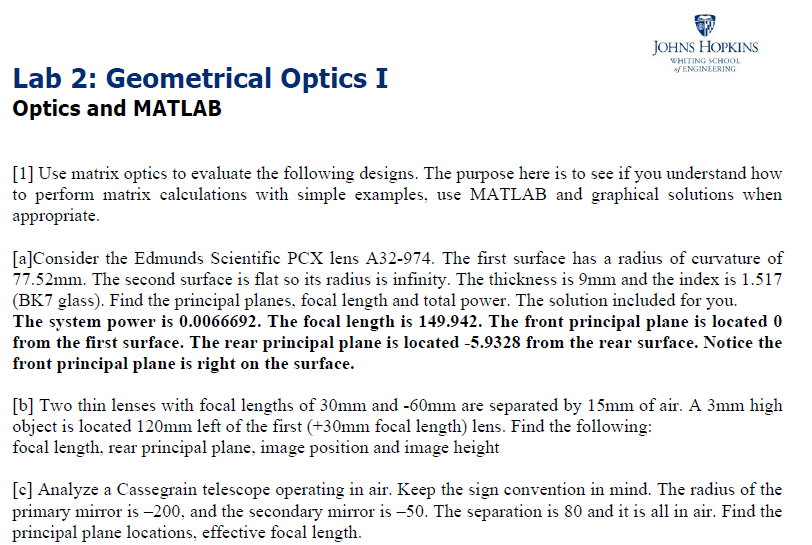

%
% Part 1.a
%
% Edmund Scientific PCX lens A32-974
% https://www.edmundoptics.com/p/500mm-dia-x-1500mm-fl-uncoated-plano-convex-lens/2743/
%
% BK7 glass n2 = 1.517
%

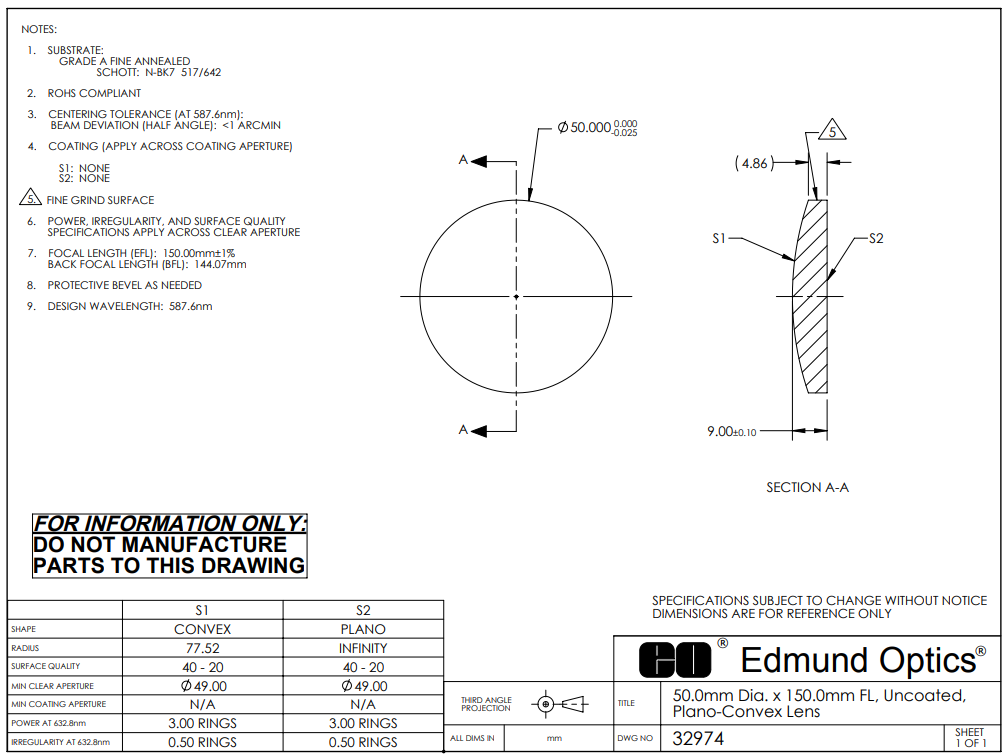

%
% Find principal planes, focal length, and total power
%
% Constants
%
n1 = 1.0; % Air/vacuum
n2 = 1.517; % BK7 Glass
S1_radius = 77.52; % millimeters
S2_radius = 1e30;  % Infinite millimeters (use large number for calculations)
thickness = 9.00; % millimeters
diameter = 50.00; % millimeters
aperture = 49.00; % millimeters
cylindrical_thickness = 4.86; % millimeters
%
% Calculate S1 principal plane
%
% Lens Maker's Equation: 1/f = (n - 1) * (1/R1 - 1/R2).
%
one_over_focal_length = (n2 - 1) * (1/S1_radius - 1/S2_radius);
focal_length = 1/one_over_focal_length;

S1_principal_plane = -thickness + (thickness * (n2-1))/n2;

**For flat side - this will be the first principal plane:**

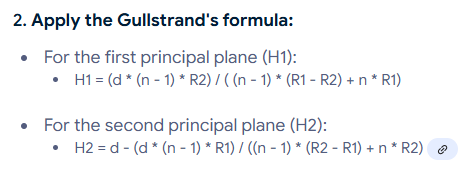

S2_principal_plane = (thickness * (n2 - 1) * S1_radius)/((n2-1)*(S2_radius - S1_radius) + n2*S2_radius);
%
% Calculate lens power - P = 1/f; % f must be in SI - meters
%
focal_length_SI = focal_length/1000; % mm to meters
P = 1/focal_length_SI; % Convert to diopters.
%
% Display results
%
msg_string = sprintf('Focal length = %4.3f mm\nS1 Principal Plane = %4.3f mm',focal_length,S1_principal_plane);
msg_string2 = sprintf('%s\nS2 Principal Plane = %4.3f mm\nPower = %4.3f Diopters',msg_string,S2_principal_plane,P);
disp(msg_string2);

Focal length = 149.942 mm
S1 Principal Plane = -5.933 mm
S2 Principal Plane = 0.000 mm
Power = 6.669 Diopters


uiwait(msgbox(msg_string2,'Part_1a'));
%
% ******************************************************************
% Part 1b
%

**Part 1[b] repeated for convenience**

From Wikipedia:

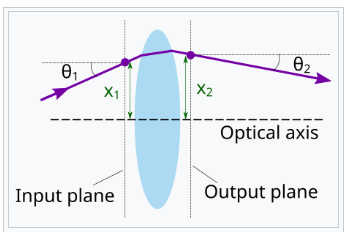 

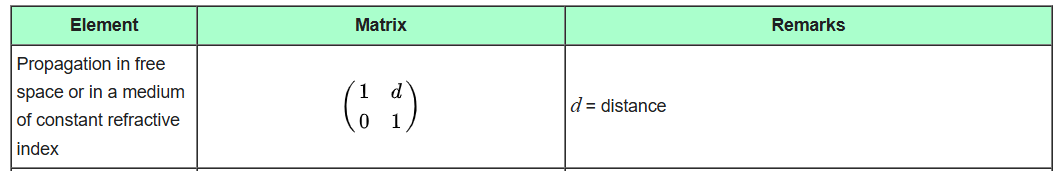

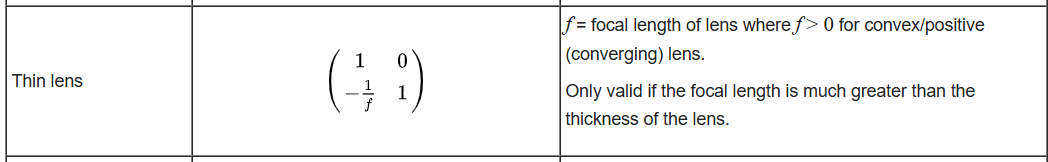

The parameters are as follows:


$$\begin{array}{l}
x_1 =3\;\textrm{mm}\\
d_1 =120\;\textrm{mm}\\
f_1 =30\;\textrm{mm}\\
d_2 =15\;\textrm{mm}\\
f_2 =-60\;\textrm{mm}\\
d_3 =60\;\textrm{mm}
\end{array}$$


%
% Input Parameters (in SI)
%
x1 = 3e-3; % Object height
d1 = 120e-3; % Distance to first lens
f1 = 30e-3; % Focal length first lens
d2 = 15e-3; % Distance between thin lenses
f2 = -60e-3; % Distance
%
% Calculate lens matrix
%
lens1_matrix = [1 0; -1/f1 1];
space_matrix = [1 d2; 0 1];
lens2_matrix = [1 0; -1/f2 1];
system_matrix = lens2_matrix*space_matrix*lens1_matrix;
system_matrix % Print out system matrix

system_matrix =     0.5000    0.0150
  -25.0000    1.2500


Given the above system matrix, focal length is such that,


$$-\frac{1}{f}=-25\ldotp 0000$$


f_system = -1/system_matrix(2,1);
fprintf('Focal Length of System = %1.3f mm',f_system*1000);

Focal Length of System = 40.000 mm

Given that 


$$\begin{array}{l}
\frac{1}{f}=\frac{1}{S_1 }+\frac{1}{S_2 }\\
\textrm{and}\;f=40\;\textrm{mm}\;\textrm{while}\;S_1 =120\;\textrm{mm},\textrm{find}\;S_2 \;\left(d_3 \right)
\end{array}$$


d3 = 1/(1/f_system - 1/d1);
fprintf('Distance from output to image is:  %1.3f mm',d3*1000);

Distance from output to image is:  60.000 mm

theta1 = atan(x1/d1);
input_matrix = [x1; theta1]

input_matrix =     0.0030
    0.0250


output_matrix = system_matrix * input_matrix

output_matrix =     0.0019
   -0.0438


x2 = output_matrix(1)*sign(output_matrix(2));
fprintf('Output image is %1.0f mm high',output_matrix(1)*1000*sign(output_matrix(2)));

Output image is -2 mm high

message = sprintf('Placing the image at 0 mm, the first principal plane is at %1.0f mm,\n',-d3*1000);
message1 = sprintf('%sthe second principal plane is at %1.0f mm,\n',message,-(d3+d2)*1000);
message2 = sprintf('%sand the object is at %1.0f mm.\n',message1,-(d3+d2+d1)*1000);
message3 = sprintf('%sFocal length = %1.0f mm and image height = %1.0f mm.',message2,f_system*1000,x2*1000);
disp(message3);

Placing the image at 0 mm, the first principal plane is at -60 mm,
the second principal plane is at -75 mm,
and the object is at -195 mm.
Focal length = 40 mm and image height = -2 mm.


uiwait(msgbox(message3,'Part_1b'));
%
% ***************************************************************
%
% Part 1c - Cassegrain Telescope
%

Mirror Matrix

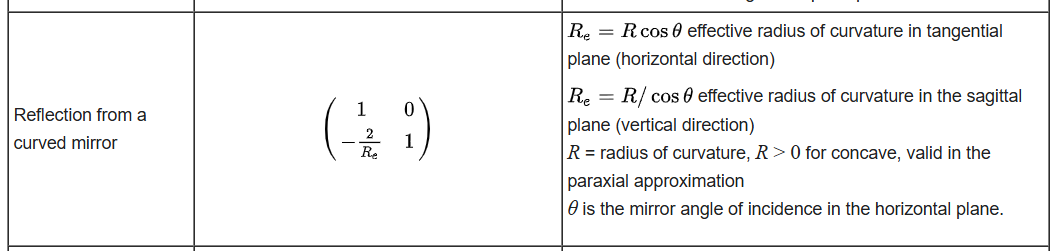

Note:  While primary mirror is given in a negative radius, we will assume it is positive due to mirror conventions,

and the secondary mirror is negative.  We will assume units in millimeters.

For mirror principal plane calculation, use n=1.5 as an equivalent refractive index.

%
% Constants
%
Rprimary = 200e-3; % meters
Separation = 80e-3; % meters
Rsecondary = -50e-3; % meters
%
% Compute matrices
%
Primary_mirror = [1 0; -2/Rprimary 1];
Between_mirrors = [1 Separation; 0 1];
Secondary_mirror = [1 0; -2/Rsecondary 1];
%
% Compute each mirror's focal length
%
f_mirror1 = Rprimary/2;
f_mirror2 = Rsecondary/2;
%
% Compute system focal length
%
System_mirror_matrix = Secondary_mirror*Between_mirrors*Primary_mirror;
f_system_mirrors = -1/System_mirror_matrix(2,1);
%
% Compute principal planes
% Treat "between mirrors" as n = 1.5 (while it is in air, the behavior of
% mirrors creates a lens-like equivalent of n=1.5
%

n_mirror = 1.5;
H1 = (Separation * (n_mirror - 1) * Rsecondary) / ((n_mirror - 1) ...
    * (Rprimary - Rsecondary) + n_mirror*Rprimary); % Sign change for mirrors
H2 = (Separation - (Separation * (n_mirror - 1) * Rprimary) / ((n_mirror - 1) ...
    * (Rsecondary - Rprimary) + n_mirror*Rsecondary)); % Sign change for mirrors
%
% Show results
%
message = sprintf('Principal Plane of primary mirror H1 = %1.1f mm\n',H1*1000);
message1 = sprintf('%sPrincipal Plane of secondary mirror H2 = %1.1f mm\n',message,H2*1000);
message2 = sprintf('%sEffective focal length of mirrors = %1.1f mm',message1,f_system_mirrors*1000);
disp(message2);

Principal Plane of primary mirror H1 = -4.7 mm
Principal Plane of secondary mirror H2 = 120.0 mm
Effective focal length of mirrors = 500.0 mm


uiwait(msgbox(message2,'Part_1c'));
%
% *******************************************************************
% Part 2
%

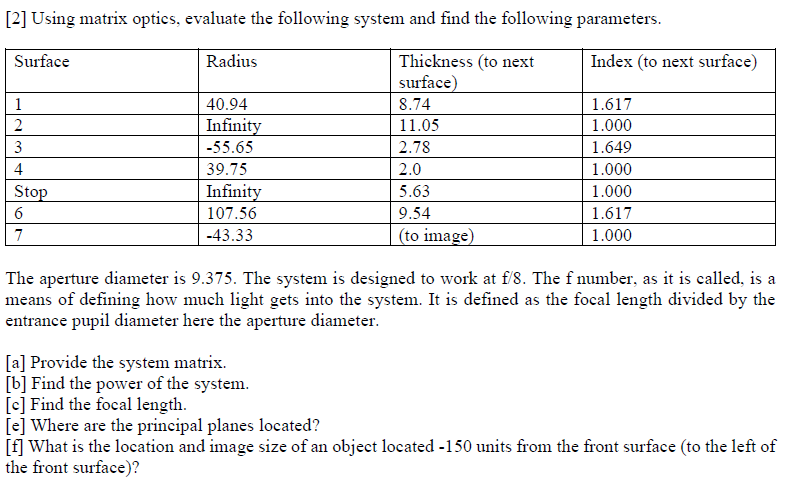

Assume all dimensioins are in mm.

%
% Constants
%
n1 = 1.000;
n2 = 1.617;
n3 = 1.649;
%
R1 = 40.94e-3; % Radius 1
T12 = 8.74e-3; % Thickness between 1 and 2 (use n2)
R2 = 1e30; % Infinite (flat) radius
T23 = 11.05e-3; % Thickness 2 to 3 (use n1)
R3 = -55.65e-3; % Radius 3
T34 = 2.78e-3; % Thickness 3 to 4 (use n3)
R4 = 39.75e-3; %Radius 4
T4stop = 2.0e-3; % Thickness 4 to stop (use n1)
Rstop = 1e30; % Infinite (flat) radius 
Tstop6 = 5.63e-3; % Thickness stop to 6 (use n1)
R6 = 107.56e-3; % Radius 6
T67 = 9.54e-3; % Thickness 6 to 7 (use n2)
R7 = -43.33e-3; % Radius 7
%
% [a] Calculate matrix
%
% System description
% 1-2:  Thick lens convex-plano surface n2 = 1.617 
% 2-3:  Air
% 3-4:  Thick lens concave-convex n3 = 1.649
% 4-stop: Air
% stop-6: Air
% 6-7: Thick lens Convex-Concave n2 = 1.617
%
Matrix12 = [1 0; (n2-n1)/(R2*n1) n2/n1]*[1 T12;0 1]*[1 0; (n1-n2)/(R1*n2) n1/n2];
Matrix23 = [1 T23;0 1];
Matrix34 = [1 0; (n3-n1)/(R4*n1) n3/n1]*[1 T34;0 1]*[1 0; (n1-n3)/(R3*n3) n1/n3];
Matrix4stop = [1 T4stop;0 1];
Matrixstop6 = [1 Tstop6;0 1];
Matrix67 = [1 0; (n2-n1)/(R7*n1) n2/n1]*[1 T67;0 1]*[1 0; (n1-n2)/(R6*n2) n1/n2];
System_matrix_part2 = Matrix67*Matrixstop6*Matrix4stop...
    *Matrix34*Matrix23*Matrix12;

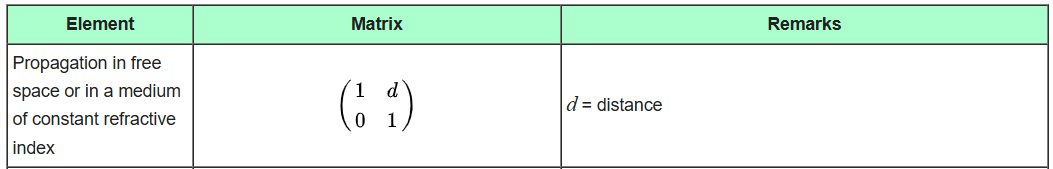

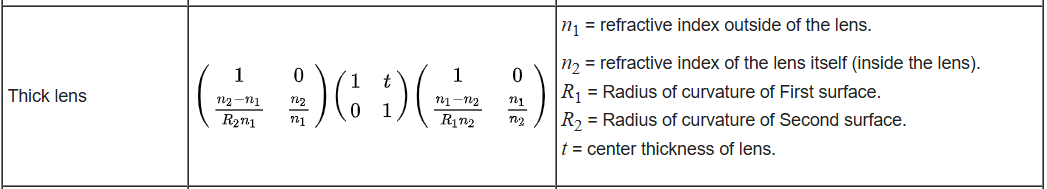

%
% [b] Calculate power
%
Power_part2 = -System_matrix_part2(2,1);
%
% [c] Focal length
%
focal_length_part2 = -1/System_matrix_part2(2,1);
%
% [d] Principal planes
%

Total_thickness_part2 = T12+T23+T34+T4stop+Tstop6+T67;
H1part2 = (Total_thickness_part2 * (n2 - 1) * R7)...
    / ((n2 - 1) * (R1 - R7) + n2*R1);
H2part2 = Total_thickness_part2...
    - (Total_thickness_part2 * (n2-1) * R1)...
    / ((n2 - 1) * (R7 - R1) + n2*R7);
%
% [e] Location and image size if object located -150mm from front surface
% Note:  Front surface at 0 mm.
% Assume object is 10 mm in height.
%

x1_part2 = 10e-3; % 1 mm for x1
position_part2 = -150e-3; % -150 mm
theta1 = atan(x1_part2/(abs(position_part2-Total_thickness_part2)));
input_matrix_part2 = [x1_part2; theta1];
output_matrix_part2 = System_matrix_part2*input_matrix_part2;
x2_part2 = output_matrix_part2(1,1)*sign(output_matrix_part2(2,1));
theta2 = output_matrix_part2(2,1);
Location_part2 = abs(x2_part2/tan(theta2));
%
% Output
%
disp('Part [2a]:');

Part [2a]:


message1 = sprintf('System Matrix:\n%2.4f %2.4f\n%2.4f %2.4f',System_matrix_part2(1,1),...
    System_matrix_part2(1,2), System_matrix_part2(2,1), System_matrix_part2(2,2));
disp(message1);

System Matrix:
0.7933 0.0377
-9.9995 0.7858


message2 = sprintf('Part [2b]:  Power = %1.2f diopter',Power_part2);
disp(message2);

Part [2b]:  Power = 10.00 diopter


%uiwait(msgbox(message,'Part_2b'));
message3 = sprintf('Part [2c]:  Focal length = %1.0f mm',focal_length_part2*1000);
disp(message3);

Part [2c]:  Focal length = 100 mm


message4 = sprintf('No part [2d]\nPart [2e]:  Principal Planes H1 = %1.1f mm H2 = %1.1f mm',H1*1000,H2*1000);
disp(message4);

No part [2d]
Part [2e]:  Principal Planes H1 = -4.7 mm H2 = 120.0 mm


message5 = sprintf('Part [2f]:  Location and image size of object\n');
message5a = sprintf('%sSize of image = %1.1f mm (object is %1.1f mm)\n',message5,x2_part2*1000,x1_part2*1000);
message5b = sprintf('%sLocation of image = %1.1f mm',message5a,Location_part2*1000);
disp(message5b);

Part [2f]:  Location and image size of object
Size of image = -9.9 mm (object is 10.0 mm)
Location of image = 169.0 mm


message_part2 = sprintf('%s\n%s\n%s\n%s\n%s',...
    message1,message2,message3,message4,message5b);
uiwait(msgbox(message_part2,'Part 2'));